# MATLAB GUIDE: Practice with Live Scripts

**Created by Kathryn Haas, Spring 2023 and refined each semester since (kh 12/08/25)**

*Before proceding, please complete the "MatLab Basics Tutorials" and "The Basics" Excercises to practice using simple commands in the command window and a regular script file. You should also install the custom scripts as described in your lab manual.*

This document is a MATLAB "Live Script" file. The default view of a Live Script file shows instructions and commands on the left, and the output on the right. You can change the view using the teeny tiny buttons along the very right side of the window. -->

- The default is "Output on right"

- When you print or export this file, "Output inline" will be the way it will be displayed.

To execute any code block in a Live Script, press **command+enter on Mac **or **control+enter on Windows**. Alternatively, you can type the commands into a regular script file or into the command window.

Practice submitting the command in the code block below. Put your cursor in the code block first, then submit using the appropriate keystrokes.

disp('I love MATLAB')

The display should appear on the right -->

You can clear the output by right clicking on the display and choosing "Clear Output". Try it!

## Loading binary files

As we saw above, ".mat" files are MATLAB binary files that store variables. Load data from the binary file "expt-1.mat" by **typing the following in the code block below**. Then execute the code.

The expt-1 binary file contains two variables; *x* and *y*, and each is an 80x1 matrix.  Notice that *x* and *y* are now listed in the workspace window. 

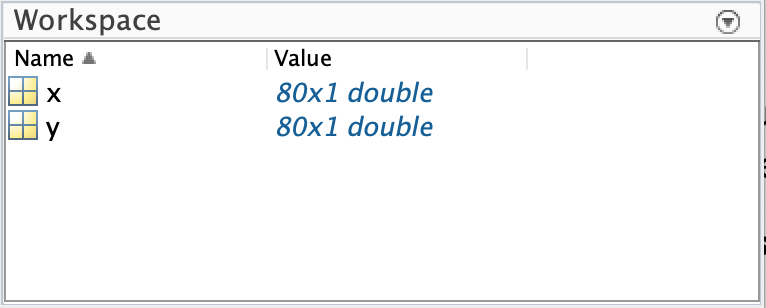

You can view the contents of a variable by typing its name in a code block. Let's view the contents of the *x* variable. In the code block below, type "x"

Now view the contents of variable *y*.

# Using a script

The simplest type of MATLAB program is a script. MATLAB scripts have the file extension ".m" or ".mlx", and to use a script file it must be in your MATLAB current folder or in a Matlab path (working directory). You can see the **current folder** under the Toolbar Ribon at the top of the MATLAB window. Mine looks like this:

You must have the lsq.mlx script in the current folder or a MATLAB working directory to proceed in this exercise; this file is a script (program) that was created for this course. If you have lsq.mlx in the correct place, you can see it in your Current Folder Window. Mine looks like this (where I've highlighted lsq.mlx by clicking on it):

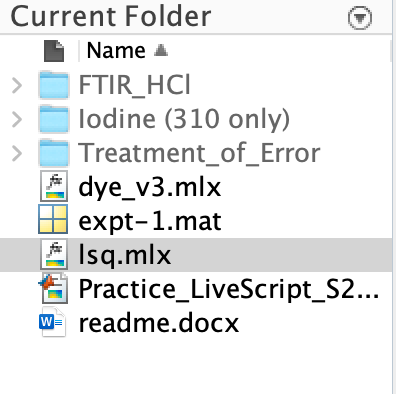

You can open the lsq script to view its contents by double clicking on the file in the Current File wondow, or by using the command "open":

The lsq LiveScript will open in a new tab in the Live Editor window. By now, you may be able to "reverse engineer" the coding in this script. And the LiveScript file contains descriptions of the code so that a human without coding experinece can interpret it. For functions that are new to you, you could use the MATLAB help features found at the top right of the screen.

A screenshot of part of the lsq is shown below:

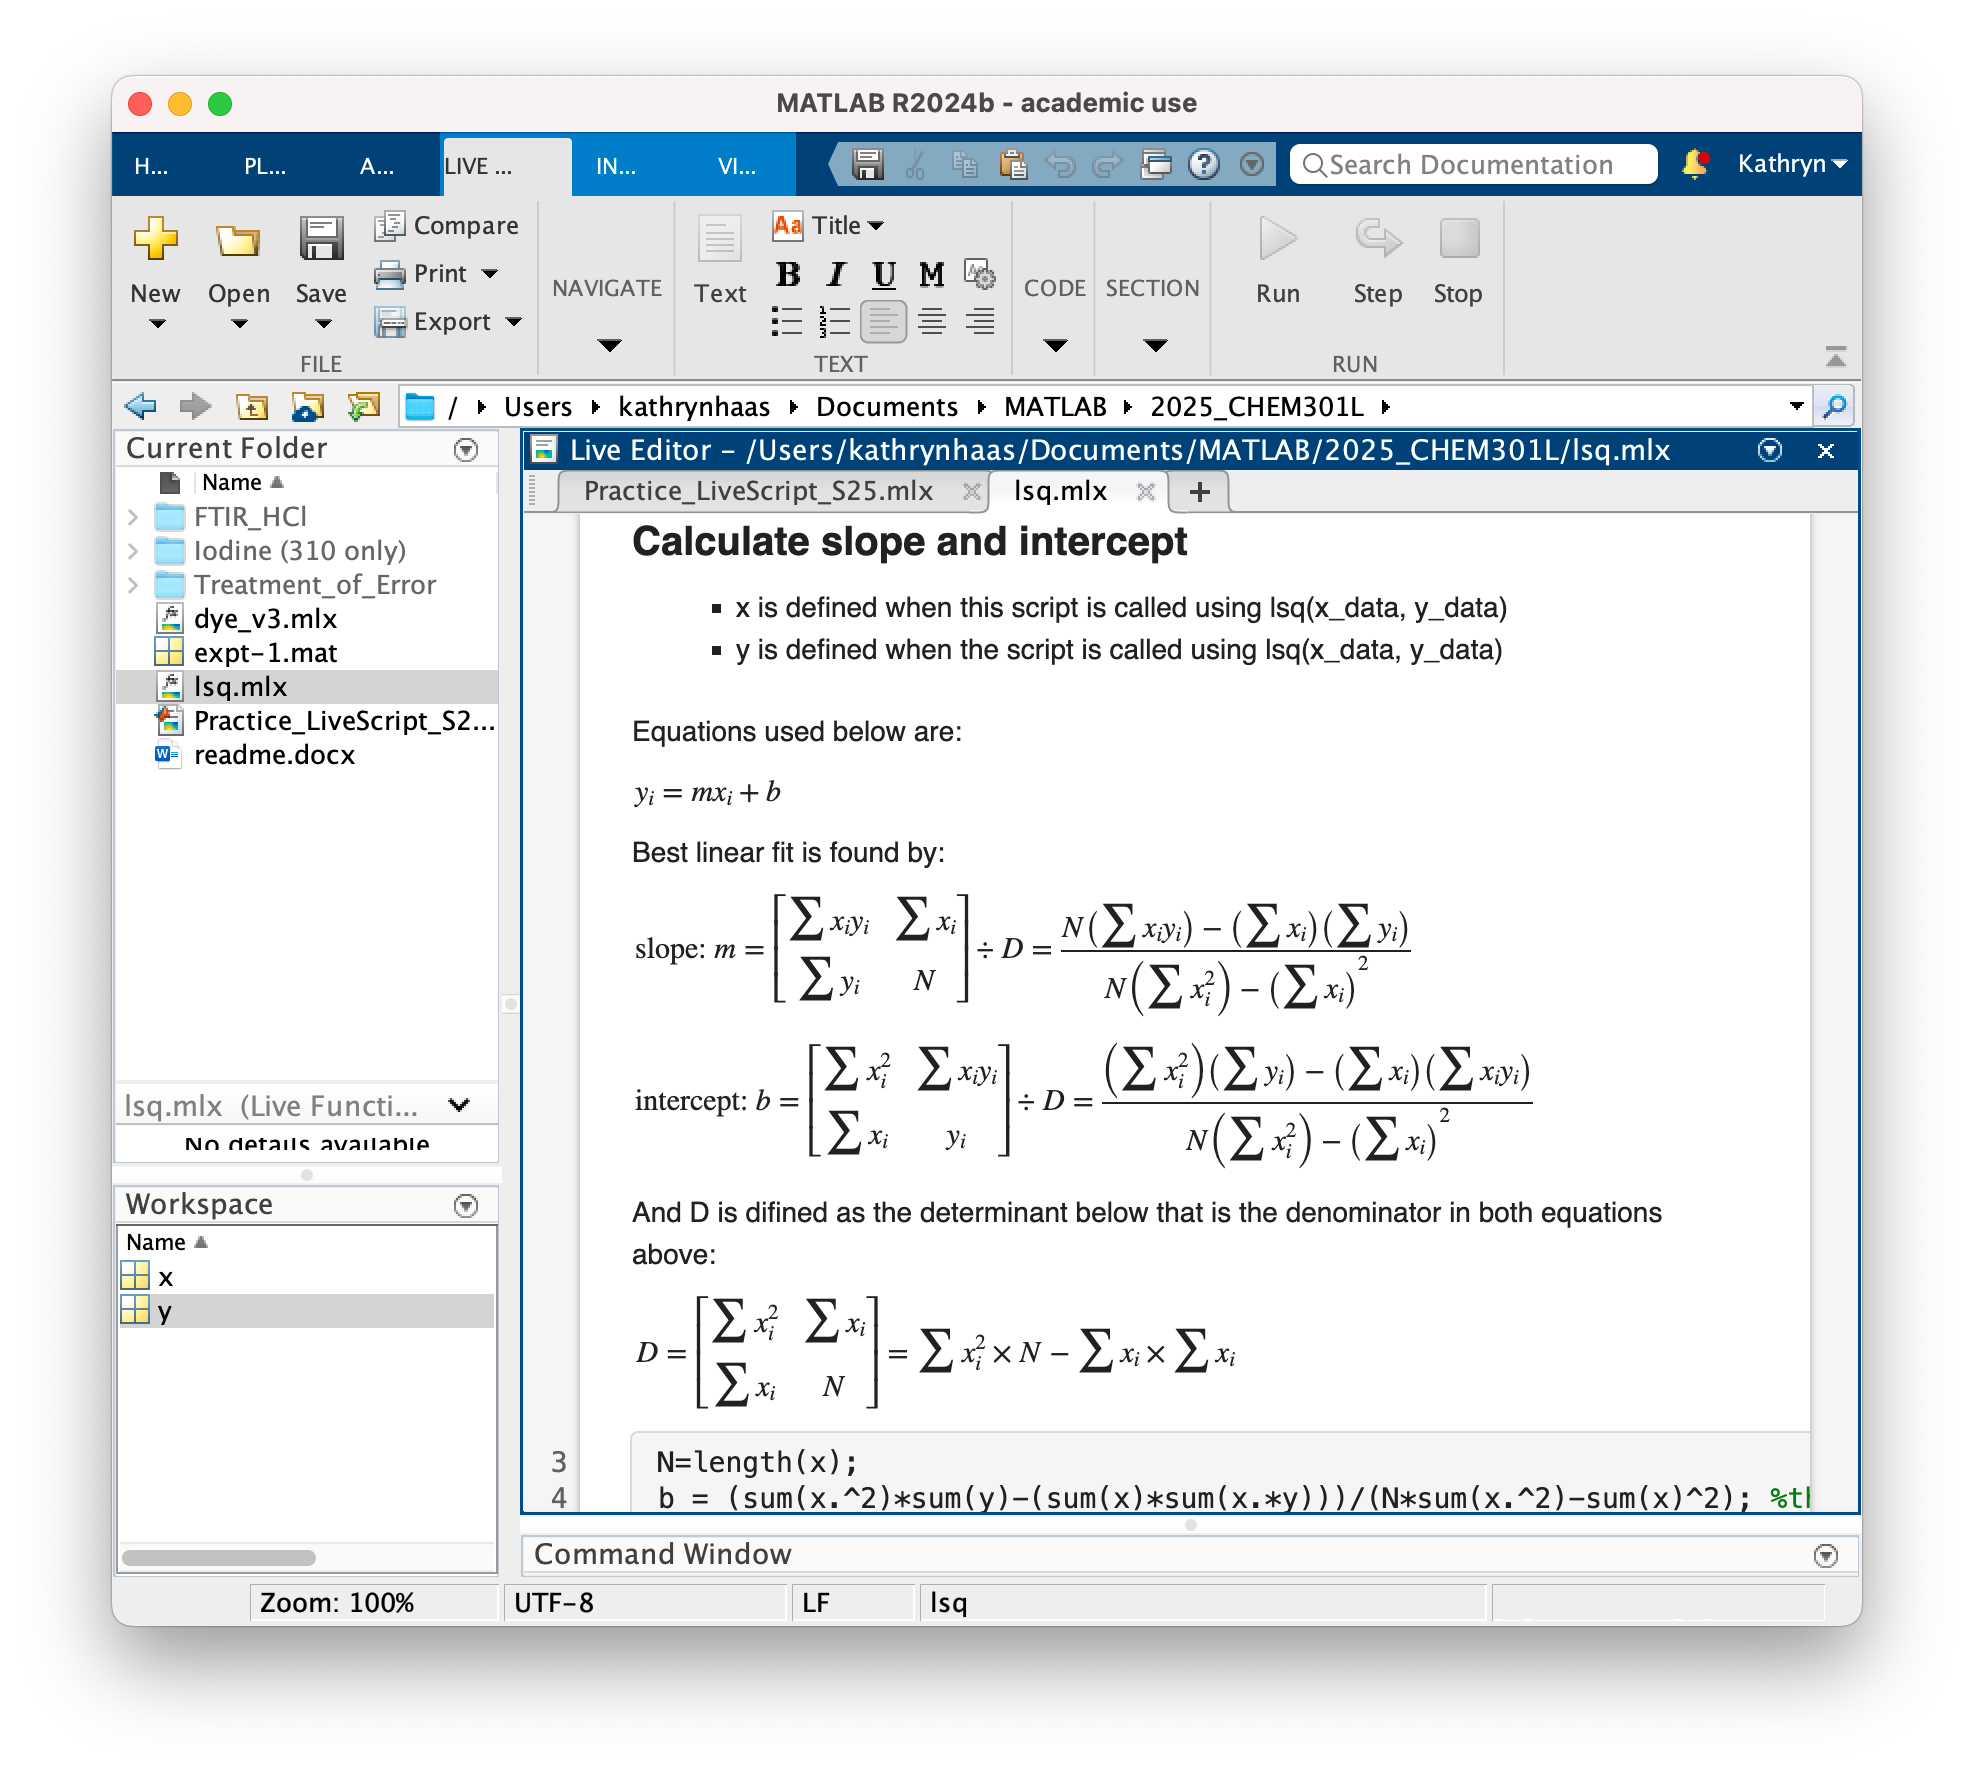

The lsq script performs least squares fitting to find the best fit **straight line **to a data set. Let's practice applying lsq.m to the *x*, *y* data. To call a script, just type its name. In the case of this particular script, we need to apply it to a set of *x* and *y* coordinates (conveniently labeled "x" and "y" in your workspace). 

Note: the output of lsq is a list of the slope and y-intercept, along with the error in both of these values. It also includes the correlation coefficient (*R*) and the standard error. The output should look like this:

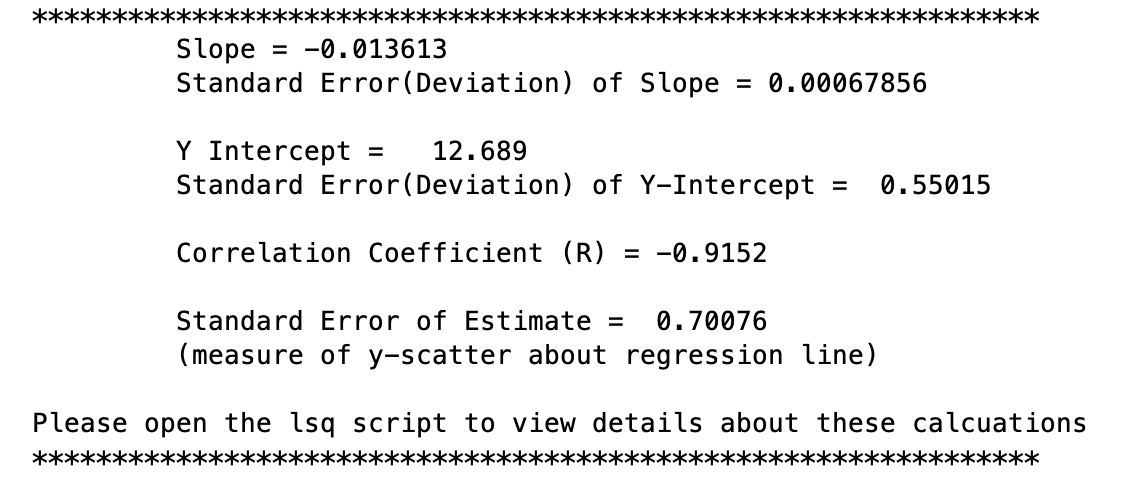

The equation of a straight line is:

 
$$y=mx+b$$


where *m* is the slope and *b* is the y-intercept.

From the *lsq* output, we can see that $m=-0\ldotp 013613\pm 0\ldotp 00067856$ and $b=12\ldotp 689\pm 0\ldotp 55015$ 

If you were reporting this output in your notebook, the equation for the line would be reported as:


$$y = [-(1.36 \pm 0.07) \times 10^{-2} ]x +[12.7\pm 0.6 ]
$$


or you could report the line formula separately from the error:

- 
$$y = -(-1.36 \times 10^{-2})x + 12.7$$


- y-intercept $= 12.7\pm 0.6$ 

- slope $= (1.36\pm 0.07) \times 10^{-2}$ 

Units should always be given, but in this case, you don't know the units because we haven't yet told you what they are.

# Plotting Data

In this course, you will present data in plotted form. **Expectation for a "final" full-credit plot in this course:**

- Data is plotted in scatter format (not line).

- Best fit line plotted as a line (not in scatter)

- Axes are correctly labeled, with correct units and  symbols.

- Axis limits are chosen to maximize view of the plotted data.

- The equation of the fitted line is shown on the plot, but not obscuring the data

- The regression stats are provided with the equation (uncertainty in slope, uncertainty in intercept, and correlation coefficient, R).

- Font and Formatting is chosen so all text is easlily readable.

- LaTex is used when appropriate to show greek letters and symbols.

- Any additional values or features specifically requested by the instructions.

Let's practice plotting the *x*, *y* data.

To plot the variable *x* vs *y* (where *x* is on the x-axis and *y* is on the y-axis, use the plot command:

Note that the output is a line plot; however, data points should always be plotted in scatter format. Add a new line of code to the box above by pressing enter.  Add a title to the code above and run it again:

Plot the data again as a scatter plot and specify the symbol "o" should be used.  Add the title "Plot data in scatter, symbol o"

The plot you just made is illegible without labeled axes and a title. Always label axes and include correct units. And always title your plots. Let's plot again and specify titles: 

## Formatting plots using code

If you'd like to change the font weight, style, size and other features using code, you can do so. For example, try the following code and observe how it changes the look of the x-axis label.

In science, we use a lot of Greek letters, superscripts, and subscripts that you may want to put on your plot. To do this, use LaTex code. If you don't know LaTex, just  google "LaTex for...." to find the right code. For example, if I want the symbol, beta, on my y axis, I should use `\beta`. 

To add a subscript 12, use an underscore with curly brackets around the number:

A superscript is accomplished with a carrot and curly brackets:

Practice formatting the axes labels using the code block above.

## Formatting plots using the GUI

Alternatively, you can change the style of a plot or its labels using the graphical user interface (GUI). Notice that if you click on the plot itself, you can use the GUI to change the plot style, titles, colors, etc. using the Figure tab from the top ribbon menu.

You can open the figure in a separate window: Click on the figure and then go to the top right corner, and click the arrow to open it in a new window.

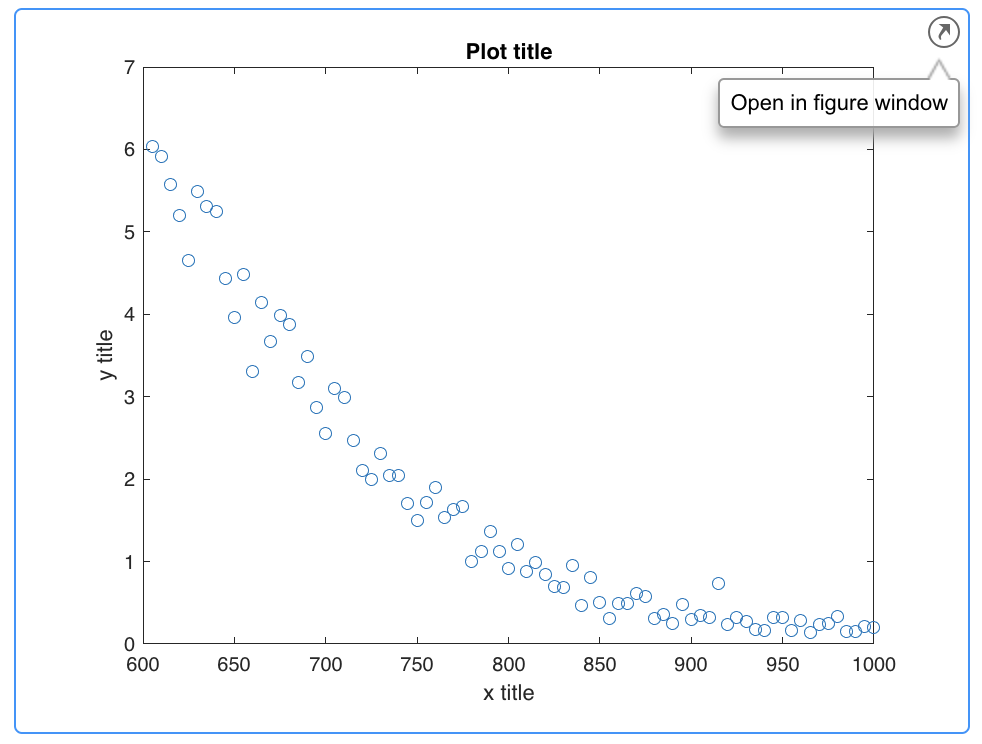

Within the figure window, you can access other menus, including fitting functions. Fit a line to the data and display both the equation and $R^2$ value on the plot. 

**Note that $R^2$ is the square of the correlation coefficient (*R*) that is output by the lsq.m script.

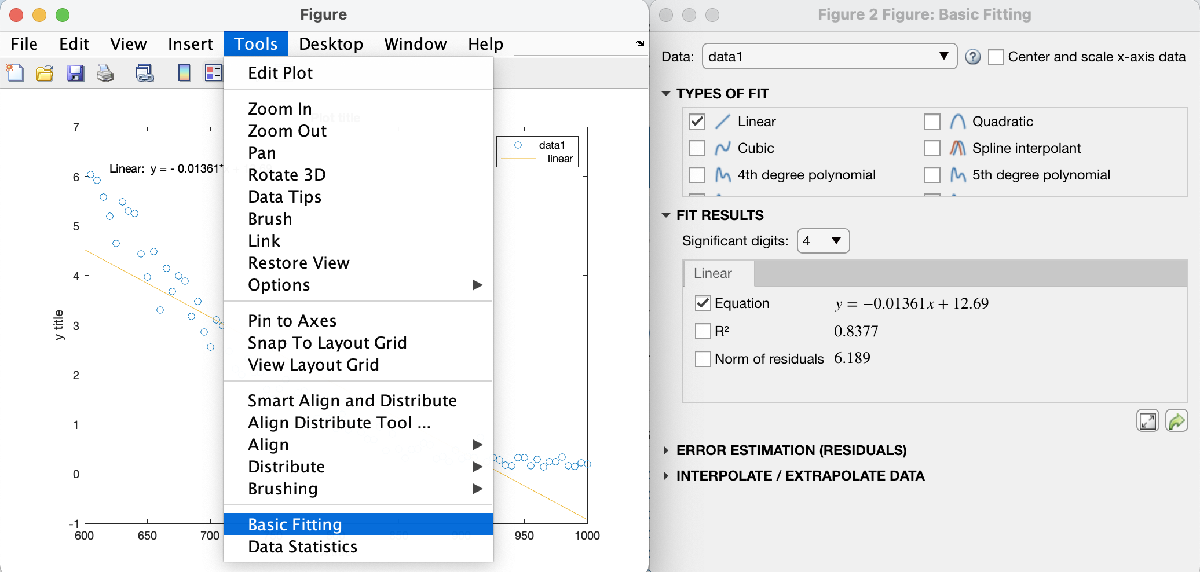

Please notice that the straight line is not a good fit to this data plotted as *x *vs *y* - yikes!  You wouldn't want to turn in this plot for a grade! Still..lets learn how to save plots so you can modify them later or use them in your lab notbooks.

## Saving Plots

**Pro tips:** 

- Always use "SAVE AS" instead of "SAVE". 

- Save every figure in two formats (1) .fig (2) .jpg

Save the plot you just made as a ".fig" file first; give it the filename "crap_plot.fig".  

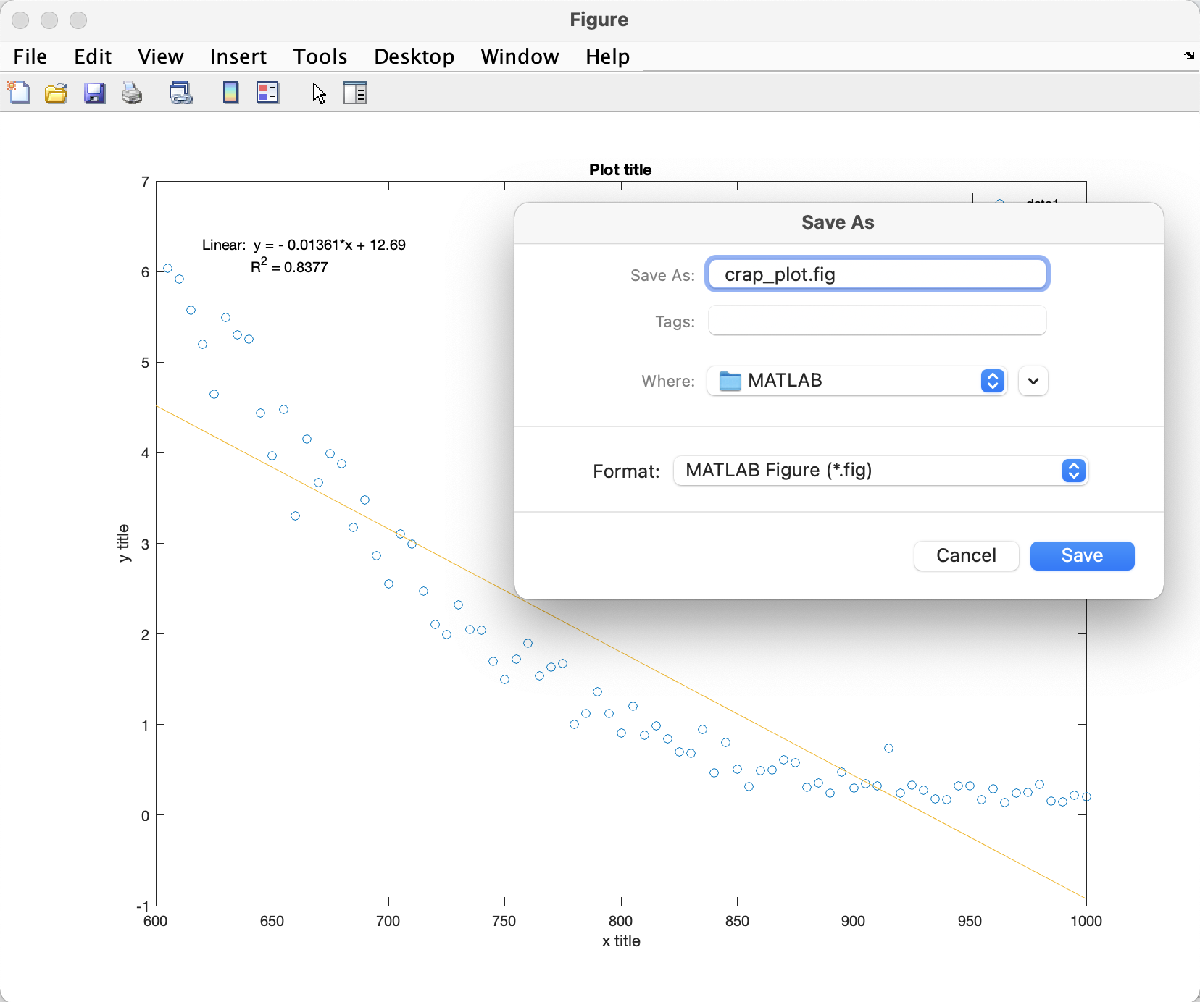

The .fig file type can be opened later and edited in MATLAB, but you will not be able to insert a .fig file as an image in MATLAB or any other program.

To save the figure as an image, select "save as" again, and change the format to .jpg or another image file format.

Insert an image of your plot with the best fit line below. To do this, go to the "Insert" tab in the top ribbon toolbar, and select "Image".

<INSERT IMAGE HERE>

# Practice

The expt-1 file contains a fake data set that you can use for practice. The variables *x* and *y *given in the *expt-1.mat *file obey the equation:


$$y= Ae^{-Cx}$$


This is the form of a first-order rate law where 

- *y* = concentration of reactant in Molarity

- x = time in seconds

- C = rate constant in inverse seconds

- A = initial concentration of reactant in Molarity

The first-order rate law can be expressed in the form of a straight line by taking the *natural log* of both sides:


$$ln(y)=-Cx + ln(A)$$
 

The MATLAB command for *natural log *of a variable is `log()`:

Use the code block below to calculate the *natural log* of y and set that value as the variable "lny".

Use the lsq script on the dataset (*x*, *lny*) to find the error in the slope and intercept for the linear form of the first-order rate law:

Then.. 

- plot *lny* versus* x*

- add titles with appropriate units

- plot the best fit line

Review the criteria for a "final" full-credit plot given above.  Create a "final" plot by adding the following:

- make sure you have descriptive titles on *x* and *y *axes with units, and a title for the plot

- the formula of the best fit line is given

- statistics from lsq (error in slope and y-intercept)

- values of A and C

Save your figure as practice_1.fig and practice_1.jpg

Insert the jpg file as an image below:

<INSERT IMAGE HERE and resize it so it is within the dimentions of the text>

## NEXT STEPS

- Export this Live Script file as a pdf. using the Live Editor toolbar tab. 

- Chek to make sure your file is legible and that all plots are visible and formated well.

- Check to make sure your plot meets all the criteria of a "final plot".

- Revise if necessary.

- Submit the pdf on Canvas.

- After you submit your work, begin the pre-lab assignment for the next meeting (see also the **Treatment_of_Error** folder that is in your Matlab directory.